# Lights peaks

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Standard textures

%     DMFWood6
%     NBglass            (Norm Bowler)
%     NBoldglass         (Norm Bowler)
%     NBwinebottle       (Norm Bowler)
%     NBbeerbottle       (Norm Bowler)
%     Ruby_Glass         (after Norm Bowler)
%     Dark_Green_Glass   (after Norm Bowler)
%     Yellow_Glass       (after Norm Bowler)
%     Orange_Glass       (after Norm Bowler)
%     Vicks_Bottle_Glass (after Norm Bowler)
%     Soft_Silver        (Dan Farmer)
%     New_Penny          (Dan Farmer)
%     Tinny_Brass        (Dan Farmer)
%     Gold_Nugget        (Dan Farmer)
%     Aluminum           (Dan Farmer)
%     Bright_Bronze      (Dan Farmer)
%     Lightening1        (Dan Farmer)
%     Lightening2        (Dan Farmer)
%     Brushed_Aluminum   (Dan Farmer)
%     Starfield          (Jeff Burton )
%     Shadow_Clouds      (Bill Pulver)

#### Create scene

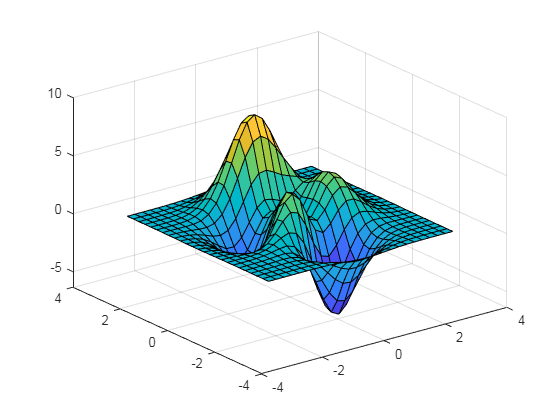

pl.scene_begin('scene_file', 'lights_peaks.pov', 'image_file', 'lights_peaks.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    pl.camera('angle', 25, 'location', [24 20 15], 'look_at', [0 -0.8 2.5], 'type', 'perspective');
    pl.light('location',  [10 10 10], 'color', [1 1 1]);
    pl.axis('length', [6 6 6]);
    
    % Light marks
    nmarks = 25;
    [x,y,z] = peaks(nmarks);
    surf(x,y,z);

    zmax = max(z, [], 'all');
    for i = 1:nmarks
        for j = 1:nmarks
            pl.sphere('position', [x(i,j) y(i,j) z(i,j)], 'radius', 0.1, 'texture', 'NBwinebottle', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
            pl.light('location',  [x(i,j) y(i,j) z(i,j)], 'color', [0.1 0.1 z(i,j) ./ zmax]);
        end
    end
    
pl.scene_end();

#### Render scene and show image

img = pl.render();
imshow(img);

Error using images.internal.getImageFromFile (line 13)
Cannot find the specified file: "C:\Program Files\MATLAB\R2021b\toolbox\pov_lab/examples/out/lights_peaks.png".

Error in images.internal.imageDisplayParseInputs (line 75)
        images.inter

#### Elapsed time

toc